Observations

numObs = 3;
obsInfo = rlNumericSpec([numObs 1]);
onsInfo.name = 'observations';

Actions

numAct = 1;
actInfo = rlNumericSpec([numAct 1],'LowerLimit',-5000,'upperLimit',5000);
actInfo.Name = 'Voltage';

mdl = "btp2";
open_system(mdl)

blk = mdl + "/RL Agent";
env = rlSimulinkEnv(mdl,blk,obsInfo,actInfo);

obsInfo = getObservationInfo(env)

obsInfo =   rlNumericSpec with properties:

     LowerLimit: -Inf
     UpperLimit: Inf
           Name: [0×0 string]
    Description: [0×0 string]
      Dimension: [3 1]
       DataType: "double"


actInfo = getActionInfo(env)

actInfo =   rlNumericSpec with properties:

     LowerLimit: 0
     UpperLimit: 5000
           Name: "Voltage"
    Description: [0×0 string]
      Dimension: [1 1]
       DataType: "double"


Critic

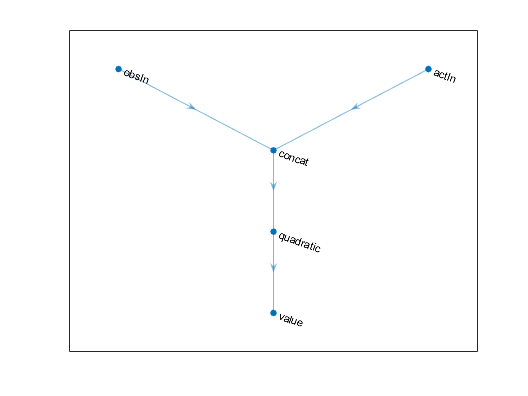

% Observation and action paths
obsPath = featureInputLayer(obsInfo.Dimension(1),Name="obsIn");
actPath = featureInputLayer(actInfo.Dimension(1),Name="actIn");

% Common path
commonPath = [
    concatenationLayer(1,2,Name="concat")
    quadraticLayer
    fullyConnectedLayer(1,Name="value", ...
        BiasLearnRateFactor=0,Bias=0)
    ];

% Add layers to layerGraph object
criticNet = layerGraph(obsPath);
criticNet = addLayers(criticNet,actPath);
criticNet = addLayers(criticNet,commonPath);

% Connect layers
criticNet = connectLayers(criticNet,"obsIn","concat/in1");
criticNet = connectLayers(criticNet,"actIn","concat/in2");

figure
plot(criticNet)


criticNet = dlnetwork(criticNet);
%summary(criticNet)

critic = rlQValueFunction(criticNet, ...
    obsInfo,actInfo, ...
    ObservationInputNames="obsIn",ActionInputNames="actIn");

getValue(critic,{rand(obsInfo.Dimension)},{rand(actInfo.Dimension)})

ans = single
-0.3126

Actor

actorNet = [
    featureInputLayer(obsInfo.Dimension(1))
    fullyConnectedLayer(actInfo.Dimension(1), ...
        BiasLearnRateFactor=0,Bias=0)
    ];

%figure
%plot(actorNet)

actorNet = dlnetwork(actorNet);
%summary(actorNet)

actor = rlContinuousDeterministicActor(actorNet,obsInfo,actInfo);

getAction(actor,{rand(obsInfo.Dimension)})

ans = 1×1 cell array
    {[-0.0808]}


Agent

agentOptions = rlDDPGAgentOptions();
agentOptions.SampleTime = 1;    % Ts
agentOptions.DiscountFactor = 0.99;
agentOptions.MiniBatchSize = 128;
agentOptions.ExperienceBufferLength = 1e6;
agentOptions.TargetSmoothFactor = 1e-3;
agentOptions.NoiseOptions.MeanAttractionConstant = 0.15;
agentOptions.NoiseOptions.Variance = 0.1;

agentOptions.ActorOptimizerOptions.Algorithm = "adam";
agentOptions.ActorOptimizerOptions.LearnRate = 1e-4;
agentOptions.ActorOptimizerOptions.GradientThreshold = 1;
agentOptions.ActorOptimizerOptions.L2RegularizationFactor = 1e-5;

agentOptions.CriticOptimizerOptions.Algorithm = "adam";
agentOptions.CriticOptimizerOptions.LearnRate = 1e-3;
agentOptions.CriticOptimizerOptions.GradientThreshold = 1;
agentOptions.CriticOptimizerOptions.L2RegularizationFactor = 2e-4;

agent = rlDDPGAgent(actor,critic,agentOptions);

Training

trainOpts = rlTrainingOptions(...
    MaxEpisodes=3000,...
    MaxStepsPerEpisode=200,...     % floor(Tf/Ts)
    ScoreAveragingWindowLength=250,...
    Plots="training-progress",...
    StopTrainingCriteria="AverageReward",...
    StopTrainingValue=210,...                   
    SaveAgentCriteria="EpisodeReward",... 
    SaveAgentValue=220);

trainingStats = train(agent,env,trainOpts);